# Compression using the Fourier Series Representation

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

Here we'll use the Fourier series to perfrom lossy compression very similar to the JPEG standard. We'll do this with an image, which, after all, is a perfectly good discrete-time signal.

Let's start by importing an image into MATLAB and getting a feel for its representation as a discrete-time signal. We'll use the famous 'Cameraman' image, which is an extremely common test image in the signal processing literature.

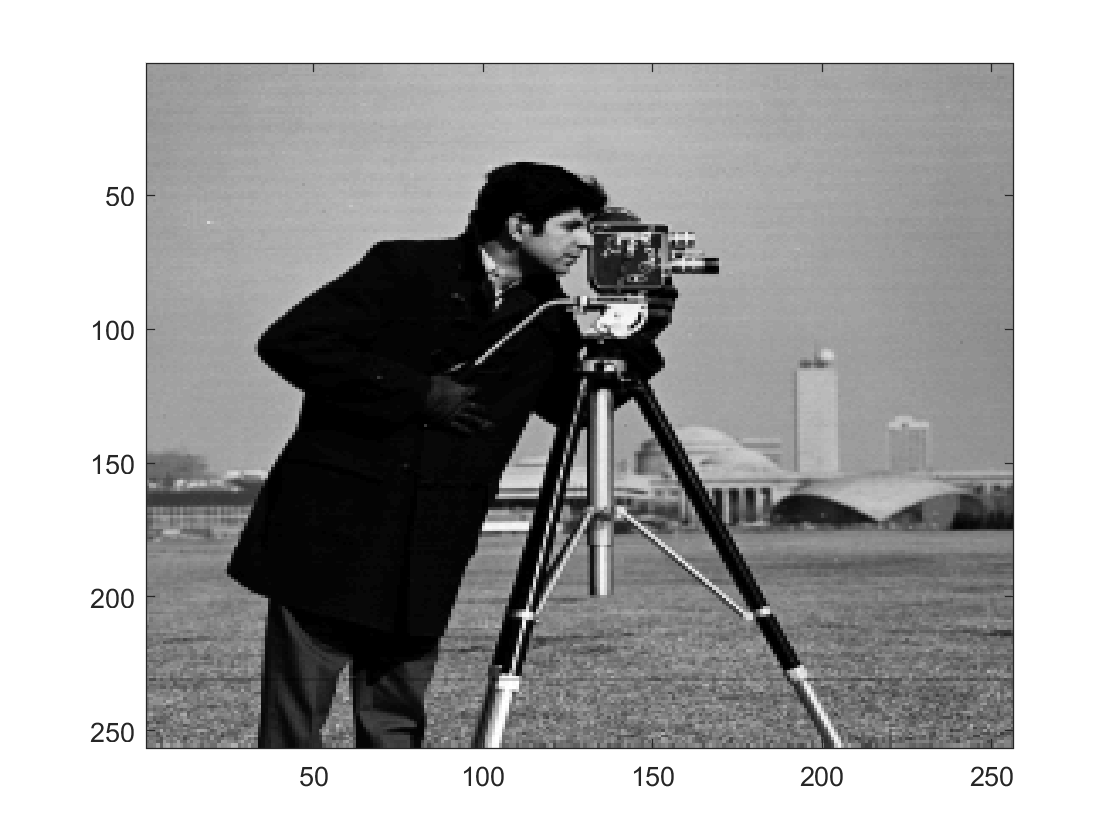

close all;
I = imread('cameraman.tif');
imagesc(I);
colormap gray;

HEIGHT = size(I,1);
LENGTH = size(I,2);

The matrix I contains the greyscale values of each pixel in the image. To process it using the Fourier series, we need to turn it into a vector signal. The MATLAB operator (:) "vectorizes" a matrix into a 1D signal that we can use as a sequence, which is just a sequence of pixel intensities from 0 to 255.

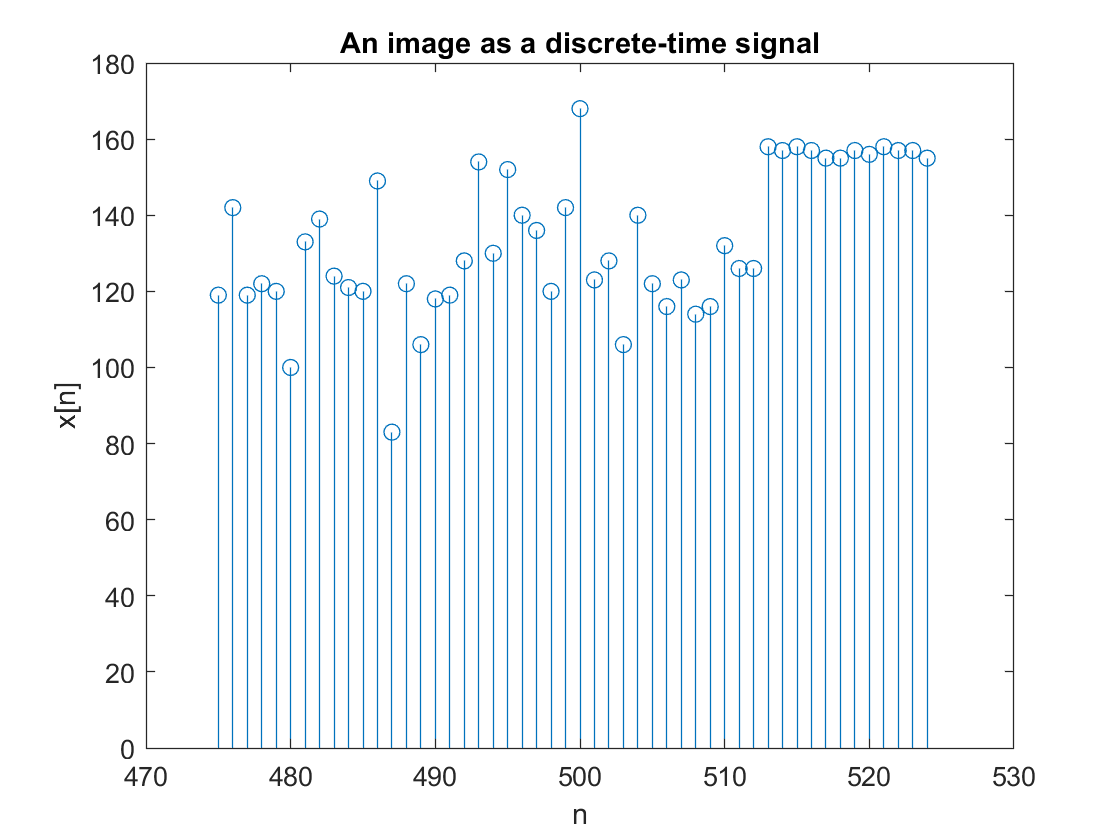

DEMO_START = 475;
DEMO_FINISH = 524;
xOriginal = I(:);

close all;
stem(DEMO_START:DEMO_FINISH,xOriginal(DEMO_START:DEMO_FINISH));
title('An image as a discrete-time signal');
xlabel('n');
ylabel('x[n]');

Now, let's compute the Fourier series reprentation of this image. We do this by considering the *periodic extention *of the signal. We treat the whole signal as if it is one period of a periodic signal. We'll use the FFT command to give us the FS coefficients. Let's look at a few of them.

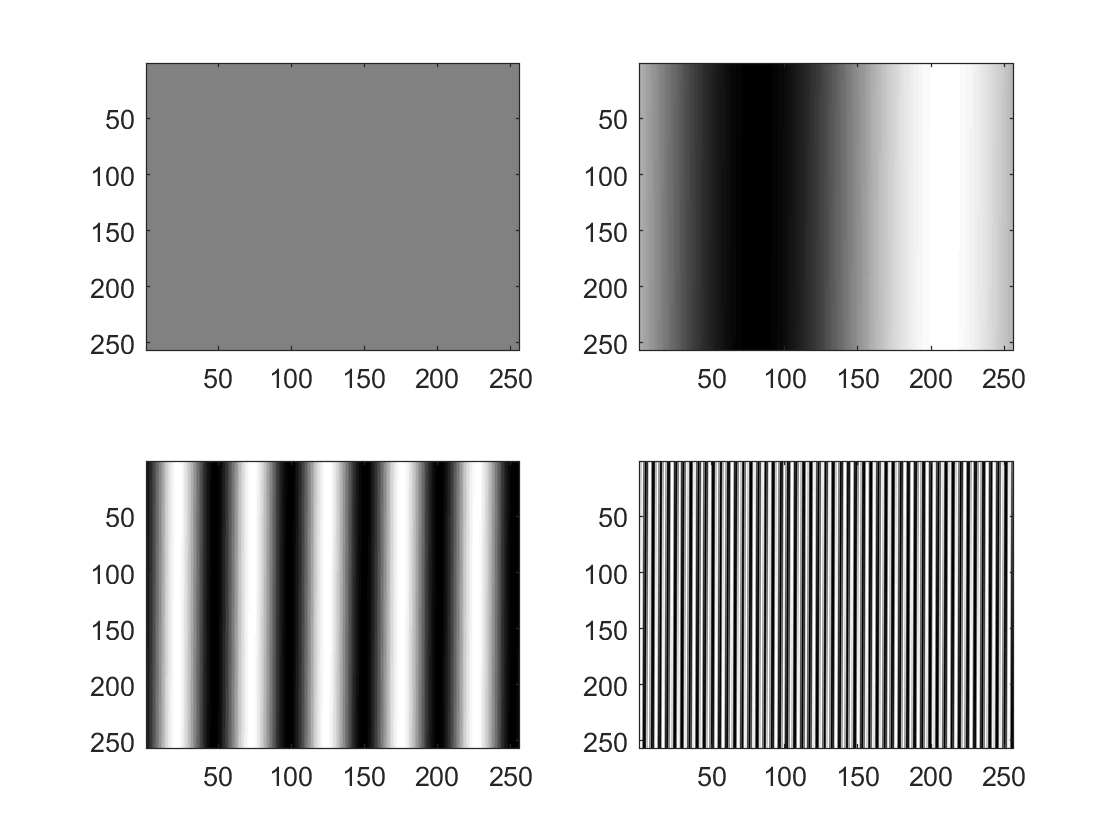

T_0 = length(xOriginal);
omega_0 = 2*pi/T_0;
a = fft(xOriginal);

x0 = a(1)*cos(0*omega_0*(1:T_0)');
x1 = 2*abs(a(2))*cos(1*omega_0*(1:T_0)' + angle(a(2)));
x5 = 2*abs(a(6))*cos(5*omega_0*(1:T_0)' + angle(a(6)));
x50 = 2*abs(a(51))*cos(50*omega_0*(1:T_0)' + angle(a(51)));
i0 = reshape(x0,HEIGHT,LENGTH);
i1 = reshape(x1,HEIGHT,LENGTH);
i5 = reshape(x5,HEIGHT,LENGTH);
i50 = reshape(x50,HEIGHT,LENGTH);

close all;
subplot(2,2,1);
imagesc(i0);
colormap gray;
subplot(2,2,2);
imagesc(i1);
colormap gray;
subplot(2,2,3);
imagesc(i5);
colormap gray;
subplot(2,2,4);
imagesc(i50);

colormap gray;

Each one of these is a single frequency component of the image. Can you convince yourself that these components make up the whole image? Let's see by adding these components up and see if we get the image we're after.

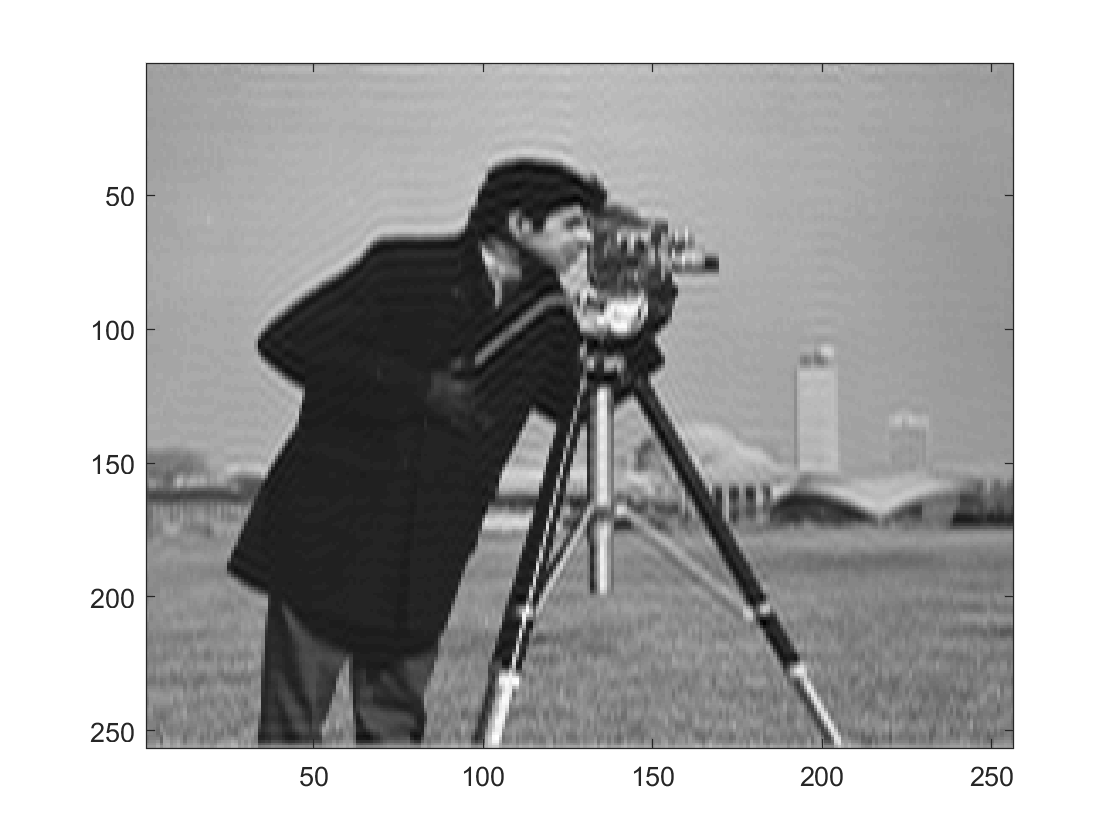

xCompressed = a(1)*ones(T_0,1); %Always include the DC component
N = 10000;
for i=2:N
    xCompressed = xCompressed + 2*abs(a(i))*cos((i-1)*omega_0*(1:T_0)' + angle(a(i)));
end %for i

iCompressed = reshape(xCompressed,HEIGHT,LENGTH);

close all;
imagesc(iCompressed)
colormap gray;

As we add more components, the reconstructed image gets closer and closer to the original. You may notice that the distortion artifacts look like JPEG artifacts. This is no coincidence! The JPEG standard performs the Discrete Cosine Transform, which is closely related to the Fourier series, on the image, and keeps only the low-frequency components. The high frequency information is thrown out to save space.